J = [2 -1];
y = 1;

x = sym("x",[2,1]);
eq1 = J*x == y

$$eq1 = 2\,x_{1}-x_{2}=1$$

eq2 = J*x == 0

$$eq2 = 2\,x_{1}-x_{2}=0$$

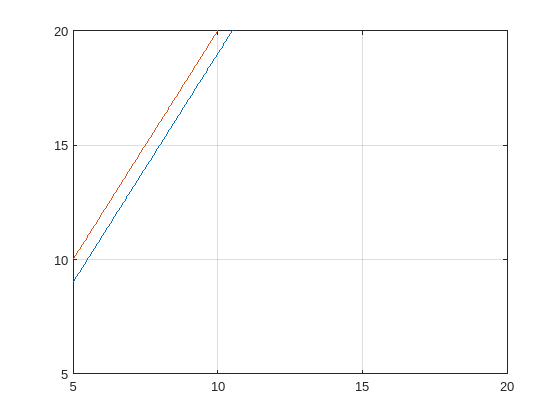

fimplicit(eq1,[5,20]); hold on;
fimplicit(eq2,[5,20]); grid;

N = [1;2]; %a basis for the nullspace of J
J_dash = pinv(J) %pseudoinverse of J

J_dash =     0.4000
   -0.2000


P = eye(size(J,2)) - J_dash*J %projection matrix onto the nullspace

P =     0.2000    0.4000
    0.4000    0.8000


x = [7;15]; %a random point which surely doesn't lie in N(J)
plot(x(1),x(2),"o")
x_p = P*x %orthogonal projection of x onto the nullspace

x_p =     7.4000
   14.8000


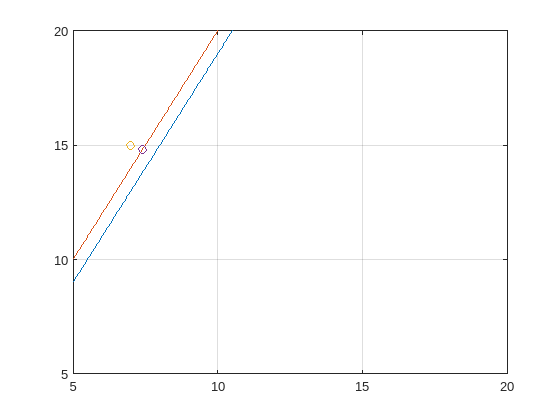

plot(x_p(1),x_p(2),"o")

J*x_p %in fact x_p lies in the nullspace of J

ans = -1.7764e-15

W = [1 -1; -1 3]; %positive definite, so always invertible
J_dash_w = W \ J' / (J * (W \ J'))

J_dash_w =     0.5556
    0.1111


Pw = eye(size(J,2)) - J_dash_w*J

Pw =    -0.1111    0.5556
   -0.2222    1.1111


x_pw = Pw*x

x_pw =     7.5556
   15.1111


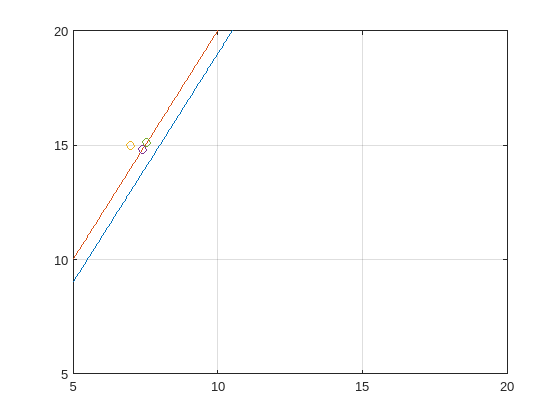

plot(x_pw(1),x_pw(2),"o")